Cleaning the workspace

clearvars
global options

Defining the configurations

configs = [
    struct('mm','sgdm','lr',0.2,'mb',256),...
    struct('mm','adam','lr',0.002,'mb',256),...
    struct('mm','sgdm','lr',0.1,'mb',256),...
    struct('mm','rmsprop','lr',0.002,'mb',256),...
    ];

Loading Training data

loadtrainingdata

Setting the Layer Setup

co = 5;

Looping through different configurations

for expNum = 1:length(configs)
    fprintf('\n=== Running Experiment %d ===\n', expNum);


Cleaning the workspace from previous expirements

    clearvars -except configs co mm  ...
        options expNum ...
        trainImages valImages testImages ...
        trainLabels valLabels testLabels ...
        imageAugmenter trainDS valDS testDS 

setting up the variables used

    cfg = configs(expNum)
    mm = cfg.mm;

displaying the configuration for tracking

    disp(cfg)

setting up the training options

    createTrainingOptions(cfg.mm,cfg.lr*cfg.mb/128,15,150,cfg.mb,valDS,floor(size(trainImages,4)/cfg.mb),0.9,true);

    setting up the layers

    conv5layers

    runing the test


=== Running Experiment 1 ===


cfg = struct with fields:
    mm: 'sgdm'
    lr: 0.1100
    mb: 256


    mm: 'sgdm'
    lr: 0.1100
    mb: 256




=== Running Training 1 ===

=== Done Training 1 ===


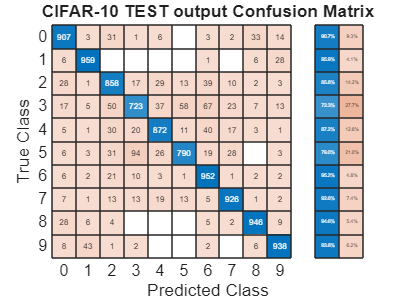

Overall Accuracy (from CM): 88.71%


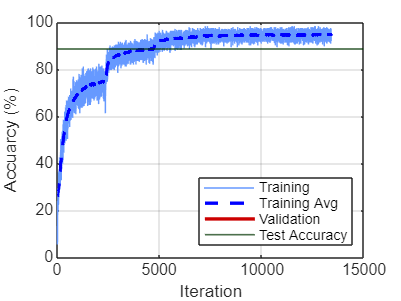

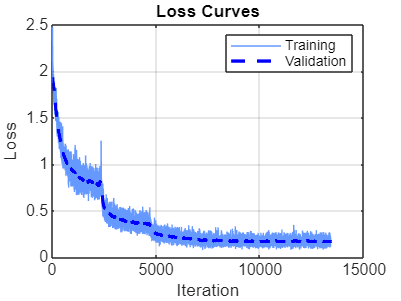


=== Running Experiment 2 ===


cfg = struct with fields:
    mm: 'sgdm'
    lr: 0.1200
    mb: 256


    mm: 'sgdm'
    lr: 0.1200
    mb: 256




=== Running Training 2 ===

=== Done Training 2 ===


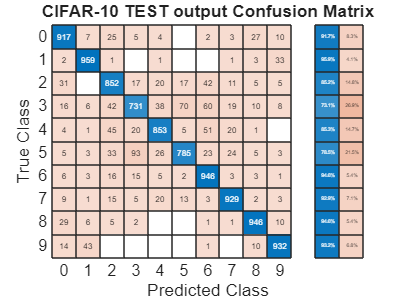

Overall Accuracy (from CM): 88.5%


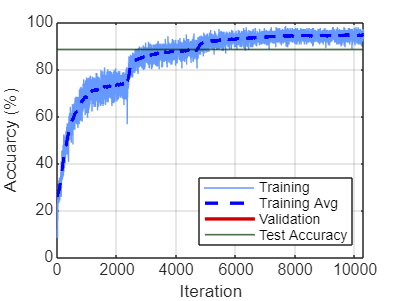

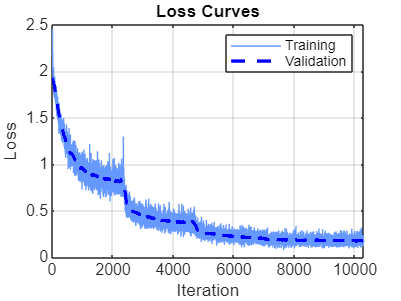


=== Running Experiment 3 ===


cfg = struct with fields:
    mm: 'sgdm'
    lr: 0.1300
    mb: 256


    mm: 'sgdm'
    lr: 0.1300
    mb: 256




=== Running Training 3 ===


    runfile
end